%% 1. Сохранить данные из файлов в переменные spectra, starNames, lambdaStart и lambdaDelta.
spectra = readtable('spectra.csv');
starnames = readtable('star_names.csv', 'ReadVariableNames', false);
lambdastart = readtable('lambda_start.csv');
lambdadelta = readtable('lambda_delta.csv');
%% 2. С помощью встроенных функций определить число наблюдений и количество исследуемых звёзд.
fprintf('Число наблюдений: %d', size(spectra, 1));

Число наблюдений: 357

fprintf('Число звёзд: %d', size(spectra, 2));

Число звёзд: 7

%% 3.Использовать оператор "двоеточие" для получения вектора длин волн lambda.
lambdaDelta=lambdadelta{1, 1}

lambdaDelta = 0.1400

lambdaStart=lambdastart{1, 1}

lambdaStart = 630.0200

lambdaEnd = lambdaStart + (size(spectra, 1)-1)*lambdaDelta;
lambda = lambdaStart:lambdaDelta:lambdaEnd

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


%% 4.Получить векторы минимальных интенсивностей и их индексов для всех звезд.
[minIntense, minIntenseindex]=min(spectra)

minIntense = 1×7 table
      Var1         Var2        Var3         Var4         Var5         Var6         Var7   
    _________    ________    _________    _________    _________    _________    _________

    1.634e-13    7.24e-14    3.144e-14    5.364e-14    6.898e-14    9.801e-14    2.214e-14


minIntenseindex = 1×7 table
    Var1    Var2    Var3    Var4    Var5    Var6    Var7
    ____    ____    ____    ____    ____    ____    ____

    188     187     188     189     189     191     185 


minIntenseIndex=table2array(minIntenseindex);
minIntense=table2array(minIntense);
StarNames=table2array(starnames)

StarNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


minLambda=656.28

minLambda = 656.2800

minIntenseIndex=lambdaStart+(minIntenseIndex-1)*lambdaDelta

minIntenseIndex =   656.2000  656.0600  656.2000  656.3400  656.3400  656.6200  655.7800


%% 5.Рассчитать скорости движения всех звезд и сохранить значения в векторе speed.
Z=(minIntenseIndex/minLambda) -1

Z = 1.0e-03 *

   -0.1219   -0.3352   -0.1219    0.0914    0.0914    0.5181   -0.7619


speed=Z*physconst("Lightspeed")

speed = 1.0e+05 *

   -0.3654   -1.0050   -0.3654    0.2741    0.2741    1.5531   -2.2840


%% 6-7
Spectra=table2array(spectra)

Spectra = 1.0e-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


hold on
for i=1:size(spectra, 2)
    if Z(i)>0
        plot(lambda, Spectra(:,i), 'LineWidth', 3);
    else
        plot(lambda, Spectra(:,i), '--', 'LineWidth', 1);
    end
end
hold off
legend(StarNames')
xline(minLambda, 'DisplayName', 'Линия Бальмер-Альфа')
 
legend()
ylabel('Интенсивность, эрг/см^2')
xlabel('Длина волны, нм')
title('Спектры звезд');
grid on
%% 8.Не используя циклы, получить вектор movaway с именами звёзд, которые удаляются от Земли.
movaway = StarNames(Z > 0);
disp('Звёзды, удаляющиеся от Земли:');

Звёзды, удаляющиеся от Земли:


disp(movaway);

    {'HD5211' }
    {'HD56030'}
    {'HD94028'}



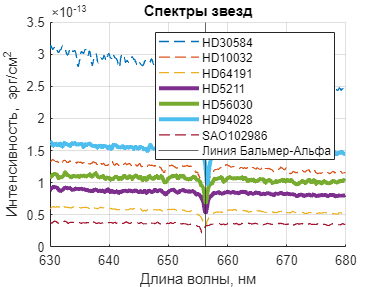


%% 9.Сохранить график как картинку в формате png.
saveas(gcf, 'filename.png')